clc;clear
options=optimset('GradObj','on','MaxIter',100);
initialTheta=zeros(3,1);
[optTheta,functionVal,exitFlag]=fminunc(@costFunction,initialTheta,options)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


optTheta =          -25.1613428736132
         0.206231791726933
         0.201471676414577


functionVal =          0.203497701589456


exitFlag =      1


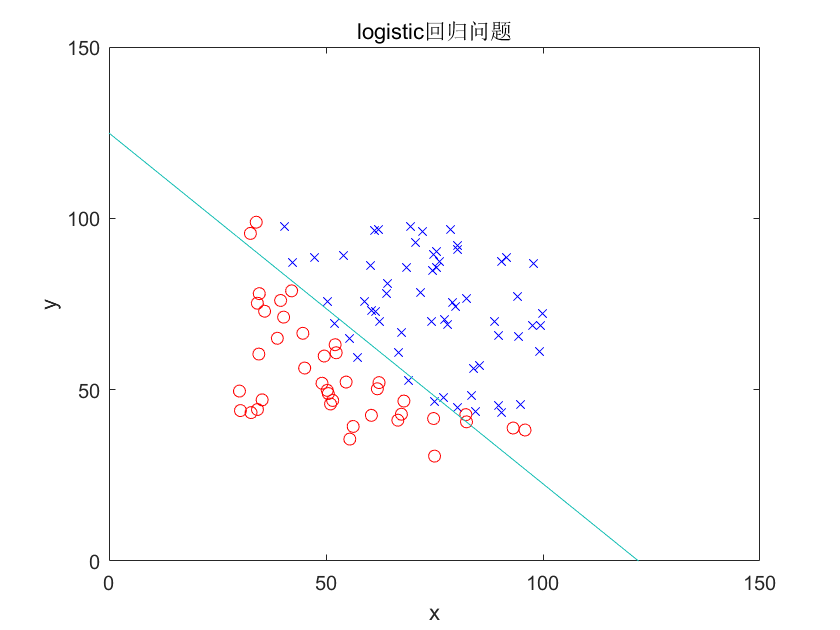

syms x y
f=optTheta(1)+optTheta(2)*x+optTheta(3)*y;

% 数据可视化
data=load('ex2data1.txt');
m=length(data);
x=data;
x(:,3)=[];
y=data(:,3);
for i=1:m
    if y(i)
        plot(x(i,1),x(i,2),'bx')
        hold on
    else
        plot(x(i,1),x(i,2),'ro')
        hold on
    end
end

ezplot(f,[0,150])
title('logistic回归问题')